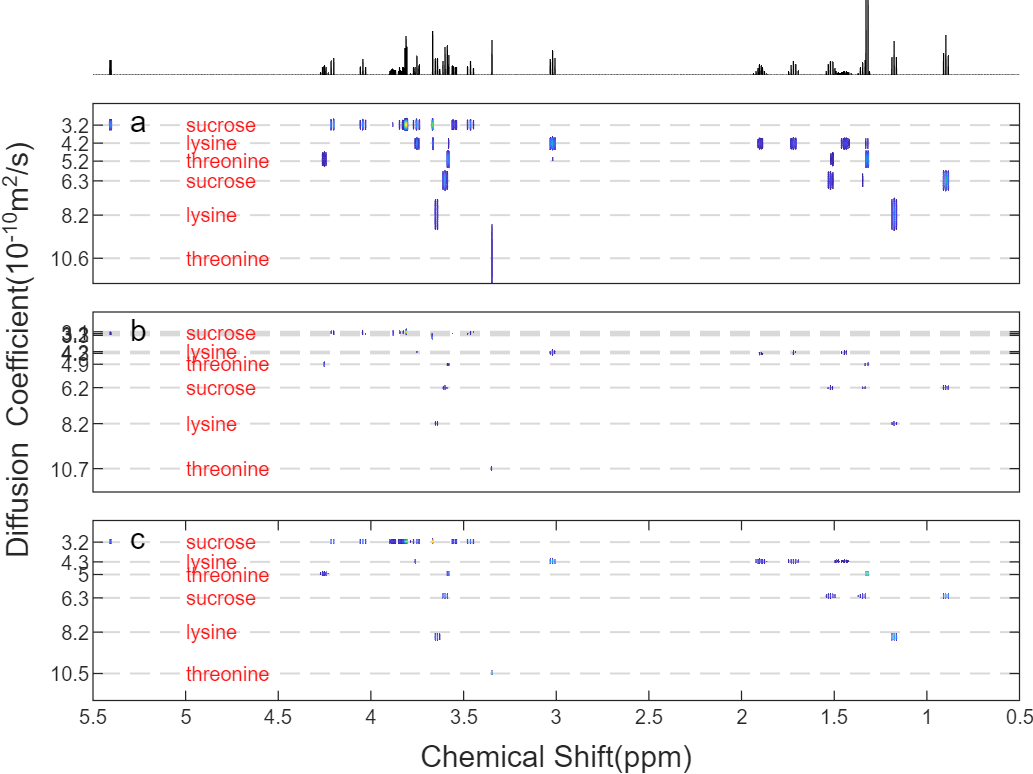

clear
load M6_b.mat
load M6_idx_peaks.mat
load M6_ppm.mat
load M6_HNMR.mat

load M6_Result.mat
load M6_Result_LRsPILT.mat
load M6_Result_CoMeF.mat
load M6_Result_CoMeF_ppm.mat

figure()
t = tiledlayout(7,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile

Type = "M6";

cs1 = 0.5;
cs2 = 5.5;
dc1 = 2;              
dc2 = 12;

contourDOSY(Type, M6_Result_LRsPILT, M6_Result_CoMeF, Z, HNMR, b, ppm, cs, idx_peaks, cs1, cs2, ...
            dc1, dc2, t);

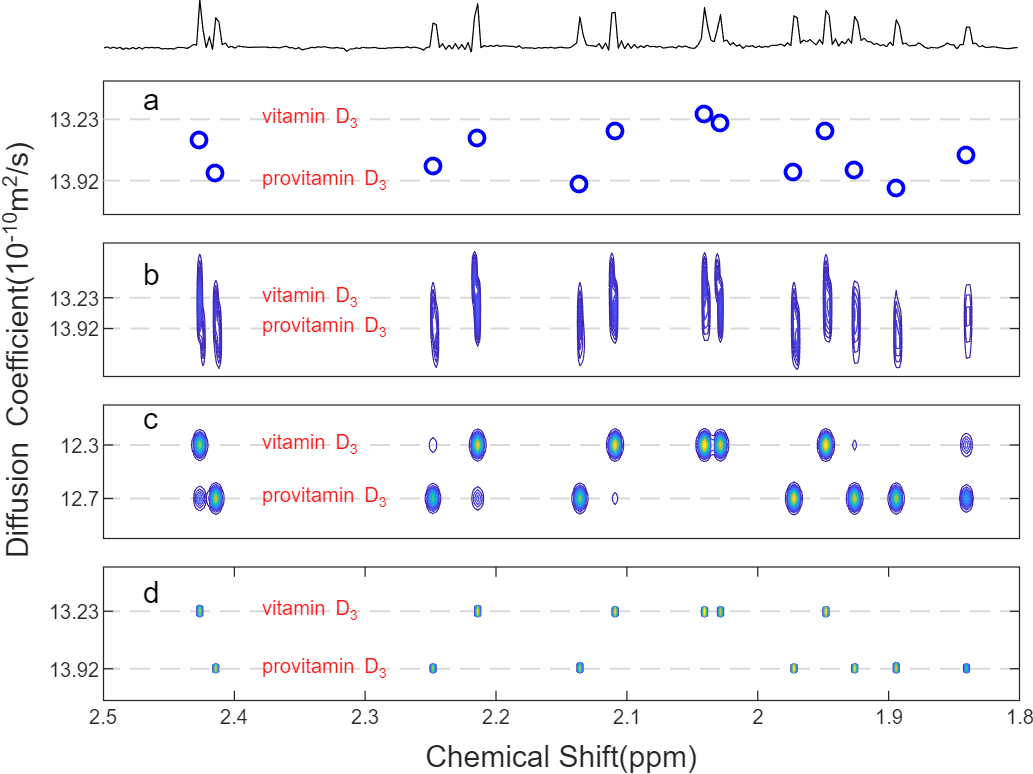

close all;clear;clc

load VD_b.mat
load VD_idx_peaks.mat
load VD_ppm.mat
load VD_HNMR.mat

load VD_Result.mat
load VD_Result_LRsPILT.mat
load VD_Result_LRsPILT_ppm.mat
load VD_Result_CoMeF.mat
load VD_result_Nlinfit.mat

figure(1)
t = tiledlayout(9,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile

Type = "VD";

cs1 = 1.8;
cs2 = 2.5;
dc1 = 12;              
dc2 = 15;

contourDOSY(Type, VD_Result_LRSpILT, VD_Result_CoMeF, Z, HNMR, b, ppm, cs, idx_peaks, cs1, cs2, ...
            dc1, dc2, t);
nexttile(2, [2, 1])
scatter(ppm, VD_Result_Nlinfit, 'MarkerEdgeColor','b',...
              'LineWidth',1.5);
ylim([12.8,14.3]);
text(2.47, 13.0, 'a', FontSize=12)
text(2.38, 13.23, "vitamin D_3", FontSize=8, Color=[1, 0.07, 0.07])
text(2.38, 13.92, "provitamin D_3", FontSize=8, Color=[1, 0.07, 0.07])

DiffCoef = [13.23, 13.92];

for i = 1:length(DiffCoef)
    l = line(gca,get(gca,'xlim'),DiffCoef(i)*ones(1,2),'LineWidth',0.8,'color',[0.85 0.85 0.85],'LineStyle','--');
    uistack(l, "bottom");
end
set(gca,'xtick',[])
set(gca,'YTick',unique(DiffCoef) )
set(gca,'Ydir','reverse','Xdir','reverse'); 
box on

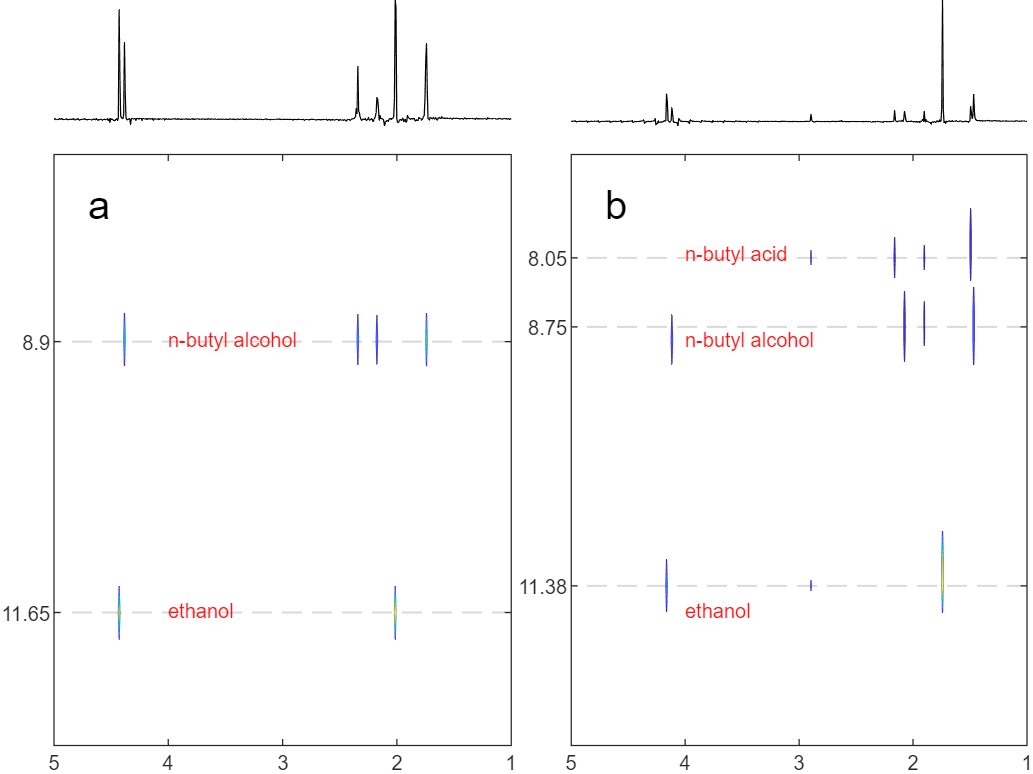

clear, clc;
load BPP1_b.mat
load BPP1_idx_peaks.mat
load BPP1_ppm.mat
load BPP1_HNMR.mat

load BPP1_Result.mat

figure()
t = tiledlayout(5, 2);
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile()
plot(ppm,HNMR, "Color",'k');set(gca,'Xdir','reverse');axis off;
cs1 = 1;
cs2 = 5;
dc1 = 7;              
dc2 = 13;
xlim([cs1,cs2]);

nexttile(3, [4, 1])

spec_whole = zeros([length(Z(1, :)), length(ppm)]);
spec_whole(:, idx_peaks) = Z.';
decay_range = linspace(0, (length(Z(1, :))-1)/10, length(Z(1, :)));
contour(ppm,decay_range*(1.2/b(end)),spec_whole,40);
set(gca,'Ydir','reverse','Xdir','reverse'); 
text(4.7, 7.5, 'a', FontSize=16)
text(4, 8.87, "n-butyl alcohol", FontSize=8, Color=[1, 0.07, 0.07])
text(4, 11.62, "ethanol", FontSize=8, Color=[1, 0.07, 0.07])

DiffCoef = [8.9, 11.65];

for i = 1:length(DiffCoef)
    l = line(gca,get(gca,'xlim'),DiffCoef(i)*ones(1,2),'LineWidth',0.8,'color',[0.85 0.85 0.85],'LineStyle','--');
    uistack(l, "bottom");
end
set(gca,'YTick',unique(DiffCoef) );

xlim([cs1,cs2]);
ylim([dc1,dc2]);

load BPP2_b.mat
load BPP2_idx_peaks.mat
load BPP2_ppm.mat
load BPP2_HNMR.mat

load BPP2_Result.mat

nexttile(2)
plot(ppm,HNMR, "Color",'k');set(gca,'Xdir','reverse');axis off;
xlim([cs1,cs2]);

nexttile(4, [4, 1])
spec_whole = zeros([length(Z(1, :)), length(ppm)]);
spec_whole(:, idx_peaks) = Z.';
decay_range = linspace(0, (length(Z(1, :))-1)/10, length(Z(1, :)));
contour(ppm,decay_range*(1.2/b(end)),spec_whole,60);
set(gca,'Ydir','reverse','Xdir','reverse'); 
text(4.7, 7.5, 'b', FontSize=16)
text(4, 8, "n-butyl acid", FontSize=8, Color=[1, 0.07, 0.07])
text(4, 8.87, "n-butyl alcohol", FontSize=8, Color=[1, 0.07, 0.07])
text(4, 11.62, "ethanol", FontSize=8, Color=[1, 0.07, 0.07])

DiffCoef = [8.05, 8.75, 11.38];

for i = 1:length(DiffCoef)
    l = line(gca,get(gca,'xlim'),DiffCoef(i)*ones(1,2),'LineWidth',0.8,'color',[0.85 0.85 0.85],'LineStyle','--');
    uistack(l, "bottom");
end
set(gca,'YTick',unique(DiffCoef) );

xlim([cs1,cs2]);
ylim([dc1,dc2]);

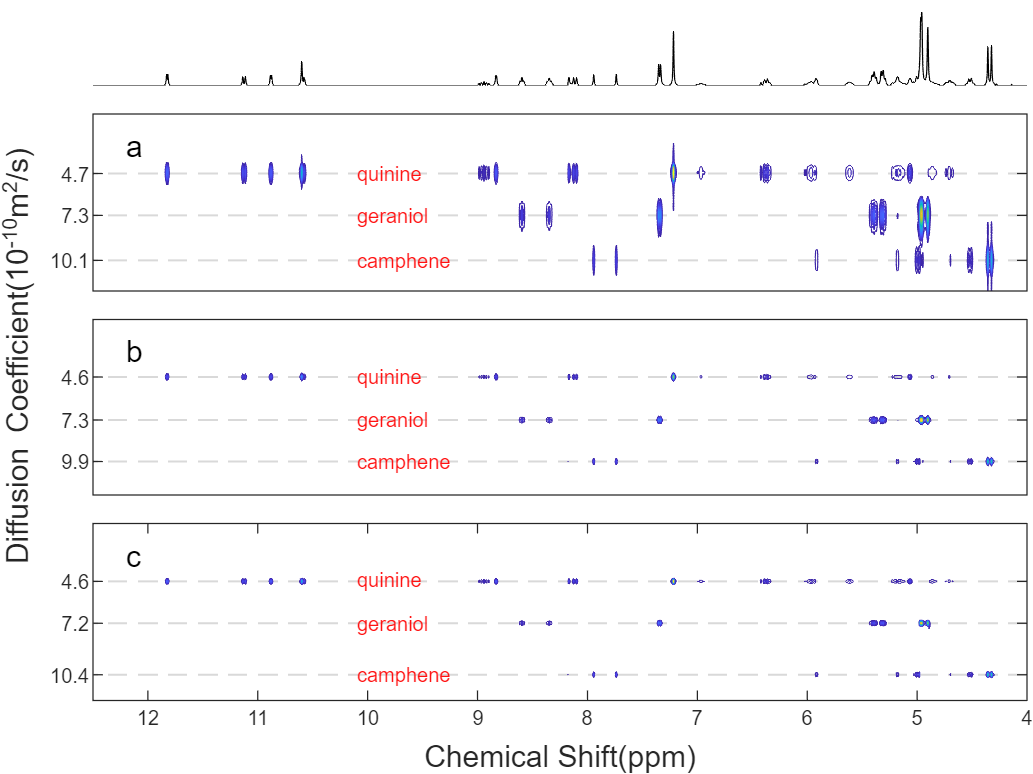

close all;clear;clc

load QGC_b.mat
load QGC_idx_peaks.mat
load QGC_ppm.mat
load QGC_HNMR.mat

load QGC_Result.mat
load QGC_Result_LRsPILT.mat
load QGC_Result_CoMeF.mat

figure()
t = tiledlayout(7,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile

Type = "QGC";

cs1 = 4;
cs2 = 12.5;
dc1 = 1;              
dc2 = 12;

cs = [];

contourDOSY(Type, QGC_Result_LRsPILT, QGC_Result_CoMeF, Z, HNMR, b, ppm, cs, idx_peaks, cs1, cs2, ...
            dc1, dc2, t);

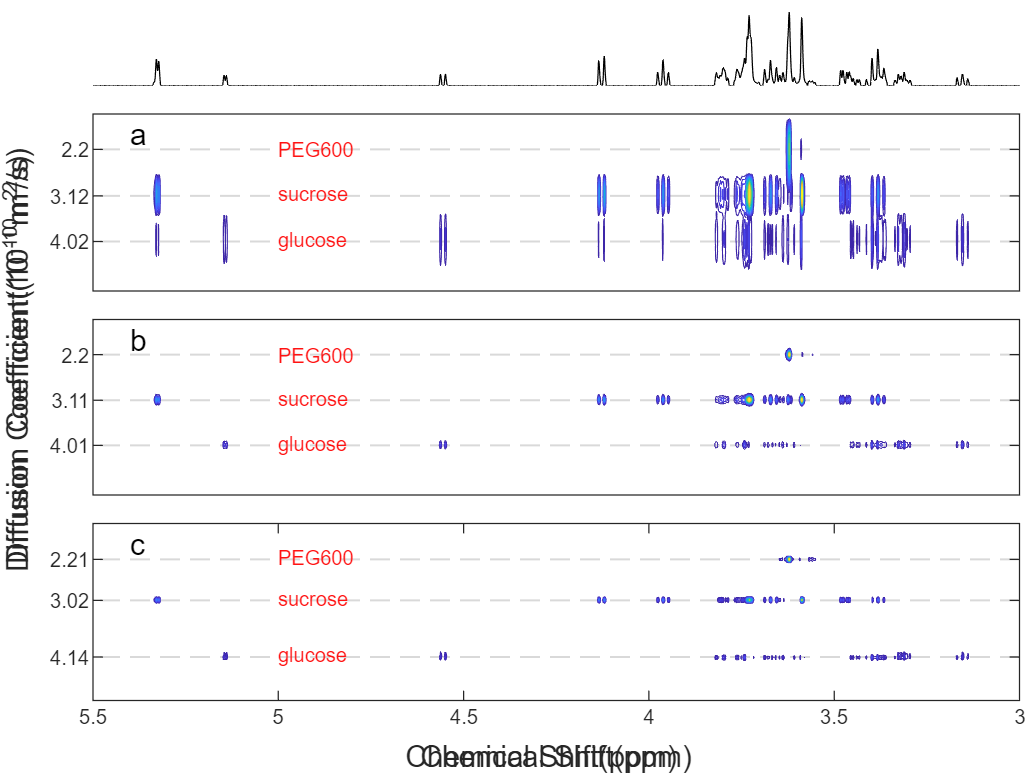

close all;clear;clc

load GSP_b.mat
load GSP_idx_peaks.mat
load GSP_ppm.mat
load GSP_HNMR.mat

load GSP_Result.mat
load GSP_Result_LRsPILT.mat
load GSP_Result_CoMeF.mat

figure()
t = tiledlayout(7,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile

Type = "GSP";

cs1 = 3;
cs2 = 5.5;
dc1 = 1.5;              
dc2 = 5;

cs = [];

contourDOSY(Type, GSP_Result_LRsPILT, GSP_Result_CoMeF, Z, HNMR, b, ppm, cs, idx_peaks, cs1, cs2, ...
            dc1, dc2, t);

close all;clear;clc

figure()

t = tiledlayout(5,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile

load T1Data.mat
load T1_net_input.mat
SResult = load('T1_Result.mat');
T1Result = zeros(1, length(S(:, 1)));
T1Result_error = zeros(1, length(S(1, :)));

T1Grad = linspace(0.01, 1, 140);
warning off
for i = 1 : length(S(:, 1))
    result = SResult.Z(i, :);
    [ipeaks, ilocs, w, p] = findpeaks(result, 'MinPeakHeight', 0.4);
    if ilocs ~= 0
        T1Result(:, i) = T1Grad(ilocs);
        T1Result_error = w/200;
    end
end

T1Data = NmrData.SPECTRA;
if size(T1Data,1)>size(T1Data,2)
    T1Data = T1Data.';  
end  
cs=NmrData.Specscale;     % chemical shift

T1Data = real(T1Data);
T1Data = -T1Data / max(T1Data(:));

T1Model = @(T1, b)(T1(1).*exp(-b ./ T1(2)));
beta0 = [2; 0.5];

T1Value = zeros(2, length(S(1, :)));
T1Value_error = zeros(2, length(S(1, :)));

opts = statset('nlinfit');
opts.RobustWgtFun = 'bisquare';

for i = 1 : length(S(:, 1))
    y = S(i, :);
    try 
        [T1Value(:, i),R,J,CovB] = nlinfit(b.', y.', T1Model, beta0, opts);
        T1Value_error(:, i) = sqrt(diag(CovB));
    catch
        T1Value(:, i) = 0;
        T1Value_error(:, i) = 0;
    end
end

whole_value = zeros(2, length(cs(1, :)));
whole_value(1, idx_peaks) = T1Value(2, :);
whole_value(2, idx_peaks) = T1Value_error(2, :);
whole_result = zeros(2, length(cs(1, :)));
whole_result(1, idx_peaks) = T1Result*32/20;
whole_result(2, idx_peaks) = T1Result_error;

T1 = abs(T1Result*32/20 -T1Value(2, :));
T1 = sort(T1);
T1_mean_error = mean(abs(T1(1:end-1)))

T1_mean_error = 0.0124

T1_max_error = max(abs(T1(1:end-1)))

T1_max_error = 0.0249


ppm = cs;
cs_spec = T1Data(1, :);
cs1 = 0.5;
cs2 = 4;
dc1 = 0.01;
dc2 = 1;

plot(ppm,cs_spec, Color='k');set(gca,'Xdir','reverse');set(gca,'Ydir','reverse');axis off;
xlim([cs1,cs2]);

nexttile(2, [2, 1])

scatter(ppm, whole_value(1, :), 36, 'MarkerEdgeColor',[0.8500 0.3250 0.0980],...
              'LineWidth',1.5, 'DisplayName','Nlinfit');
hold on;

scatter(ppm, whole_result(1, :), 36, 'MarkerEdgeColor',[0 0.4470 0.7410],...
              'LineWidth',1.5, 'Marker', '+', 'DisplayName', 'DRILT');

ylabel('T1(s)');
text(0.8, 0.15, 'a', FontSize=16)
legend(Location="northwest", Box="off")
xlim([cs1,cs2]);
ylim([dc1,dc2]);
set(gca, 'Ydir','reverse','Xdir','reverse'); 
box on

load T2Data.mat
load T2_net_input.mat
SResult = load('T2_Result.mat');

T2Result = zeros(1, length(S(:, 1)));
T2Grad = linspace(0.01, 1, 140);
for i = 1 : length(S(:, 1))
    result = SResult.Z(i, :);
    [ipeaks, ilocs, w, p] = findpeaks(result, 'MinPeakHeight', 0.3);
    if ilocs ~= 0
        T2Result(:, i) = T2Grad(ilocs);
    end
end

T2Data = NmrData.SPECTRA;
if size(T2Data,1)>size(T2Data,2)
    T2Data = T2Data.';  
end  

cs=NmrData.Specscale;     % chemical shift

T2Data = real(T2Data);
T2Data = T2Data / max(T2Data(:));

T2Model = @(T2, b)(T2(1).*exp(-b ./ T2(2)));

beta0 = [0.1; 0.3];

T2Value = zeros(2, length(S(:, 1)));
T2Value_error = zeros(2, length(S(:, 1)));

opts = statset('nlinfit');
opts.RobustWgtFun = 'bisquare';
for i = 1 : length(S(:, 1))

    y = S(i, :);
    T2Value(:, i) = nlinfit(b.', y.', T2Model, beta0);
    try 
        [T2Value(:, i),R,J,CovB] = nlinfit(b.', y.', T2Model, beta0);
        T2Value_error(:, i) = sqrt(diag(CovB));
    catch
        T2Value(:, i) = 0;
        T2Value_error(:, i) = 0;
    end

end

whole_value = zeros(2, length(cs(1, :)));
whole_value(1, idx_peaks) = T2Value(2, :);
whole_value(2, idx_peaks) = T2Value_error(2, :);
whole_result = zeros(1, length(cs(1, :)));
whole_result(1, idx_peaks) = T2Result*12.8/20;

T2 = T2Result*12.8/20 - T2Value(2, :);
T2 = sort(T2);
T2_mean_error = mean(abs(T2(2:end)))

T2_mean_error = 0.0044

T2_max_error = max(abs(T2(2:end)))

T2_max_error = 0.0265

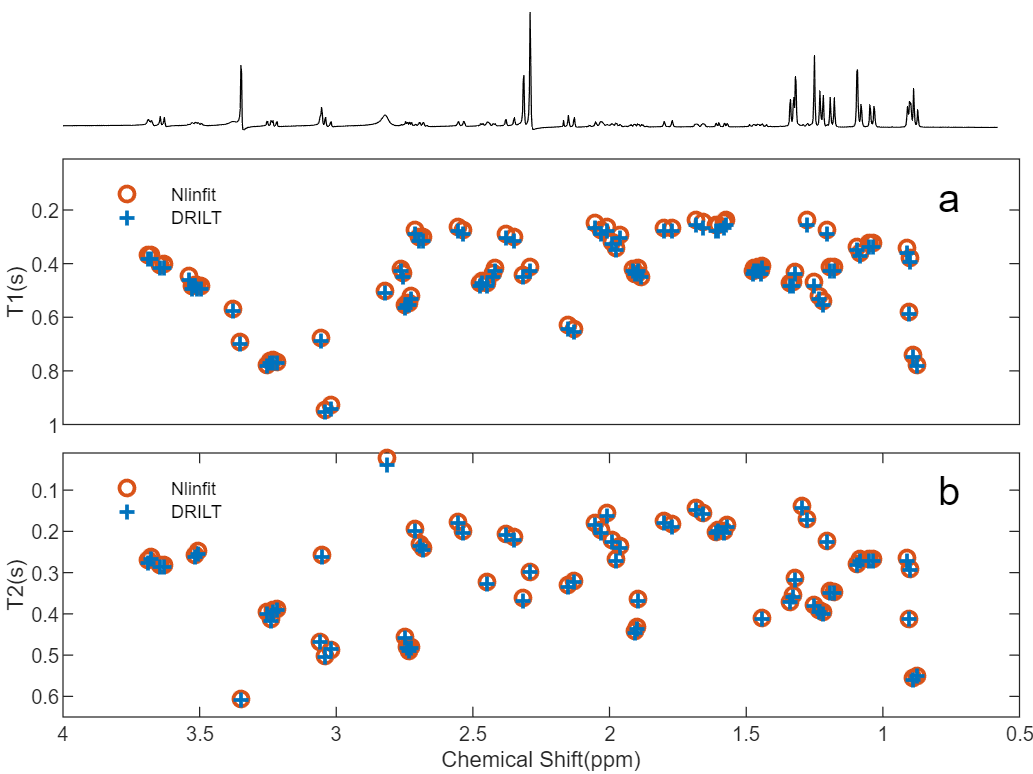


ppm = cs;
cs_spec = T2Data(1, :);
cs1 = 0.5;
cs2 = 4;
dc1 = 0.01;
dc2 = 0.65;
set(gca,'xtick',[])

nexttile(4, [2, 1])
scatter(ppm, whole_value(1, :), 'MarkerEdgeColor',[0.8500 0.3250 0.0980],...
              'LineWidth',1.5 ,'DisplayName','Nlinfit');

hold on;
scatter(ppm, whole_result, 36, 'MarkerEdgeColor',[0 0.4470 0.7410], 'LineWidth',1.5, 'Marker', '+', 'DisplayName','DRILT');
xlabel('Chemical Shift(ppm)');
ylabel('T2(s)');
legend(location='northwest', Box='off')
text(0.8, 0.1, 'b', FontSize=16)
set(gca,'Ydir','reverse','Xdir','reverse'); 
xlim([cs1,cs2]);
ylim([dc1,dc2]);
box on

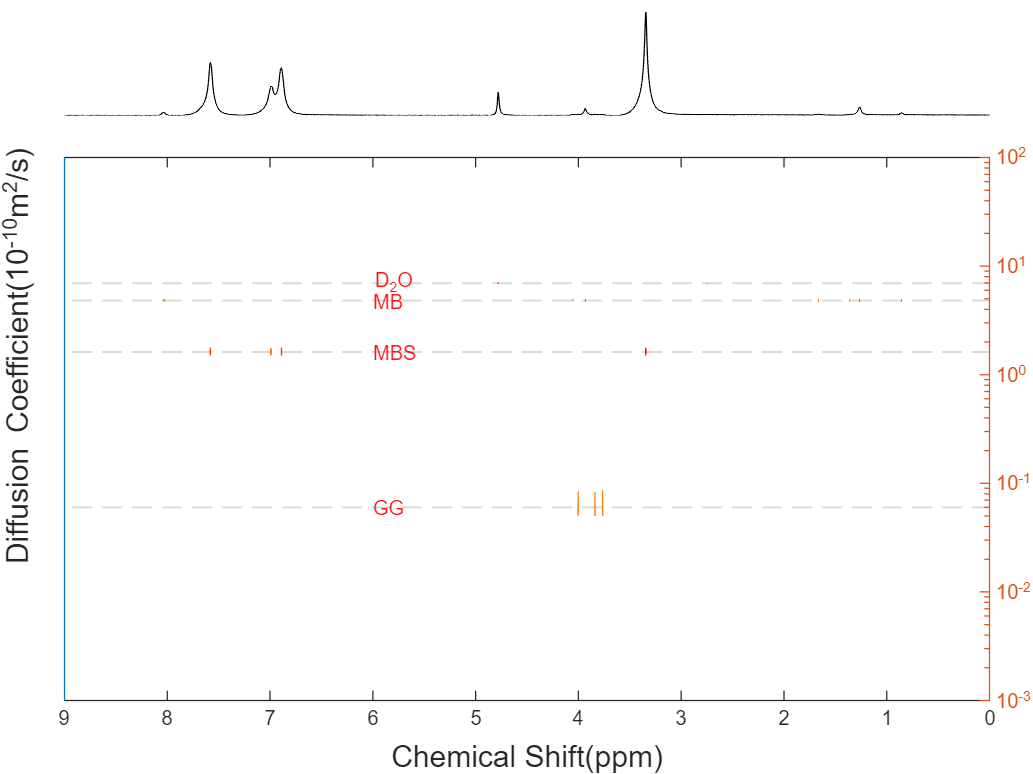

clear, clc;

load MS_low_b.mat
load MS_low_idx_peaks.mat
load MS_low_ppm.mat
load MS_low_HNMR.mat

load MS_low_Result.mat

figure()

t = tiledlayout(5, 1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

cs1 = 0;
cs2 = 9;
dc1 = 1e-3;              
dc2 = 100;

nexttile()
plot(ppm, HNMR, "Color",'k');set(gca,'Xdir','reverse');axis off;
xlim([cs1,cs2]);

nexttile(2, [4, 1])
spec_whole = zeros([length(Z(1, :)), length(ppm)]);
spec_whole(:, idx_peaks) = Z.';
decay_range = linspace(0, 7, length(Z(1, :)));
yyaxis right
[~, h] = contour(ppm,decay_range,spec_whole,160);
set(h.Parent, 'YScale', 'log')

colormap(flipud(autumn));
caxis([-1 1])
set(gca, 'Xdir','reverse'); 

DiffCoef = [0.06, 1.62, 4.82, 6.95];

for i = 1:length(DiffCoef)
    l = line(gca,get(gca,'xlim'),DiffCoef(i)*ones(1,2),'LineWidth',0.8,'color',[0.85 0.85 0.85],'LineStyle','--');
    uistack(l, "bottom");
end


text(6, 0.06, "GG", FontSize=8, Color=[1, 0.07, 0.07])
text(6, 1.62, "MBS", FontSize=8, Color=[1, 0.07, 0.07])
text(6, 4.82, "MB", FontSize=8, Color=[1, 0.07, 0.07])
text(6, 6.95, "D_2O", FontSize=8, Color=[1, 0.07, 0.07])

xlim([cs1,cs2]);
ylim([dc1,dc2]);
xlabel(t, 'Chemical Shift(ppm)');
ylabel(t, 'Diffusion Coefficient(10^{-10}m^2/s)');
yyaxis left
set(gca, 'YTick', [])

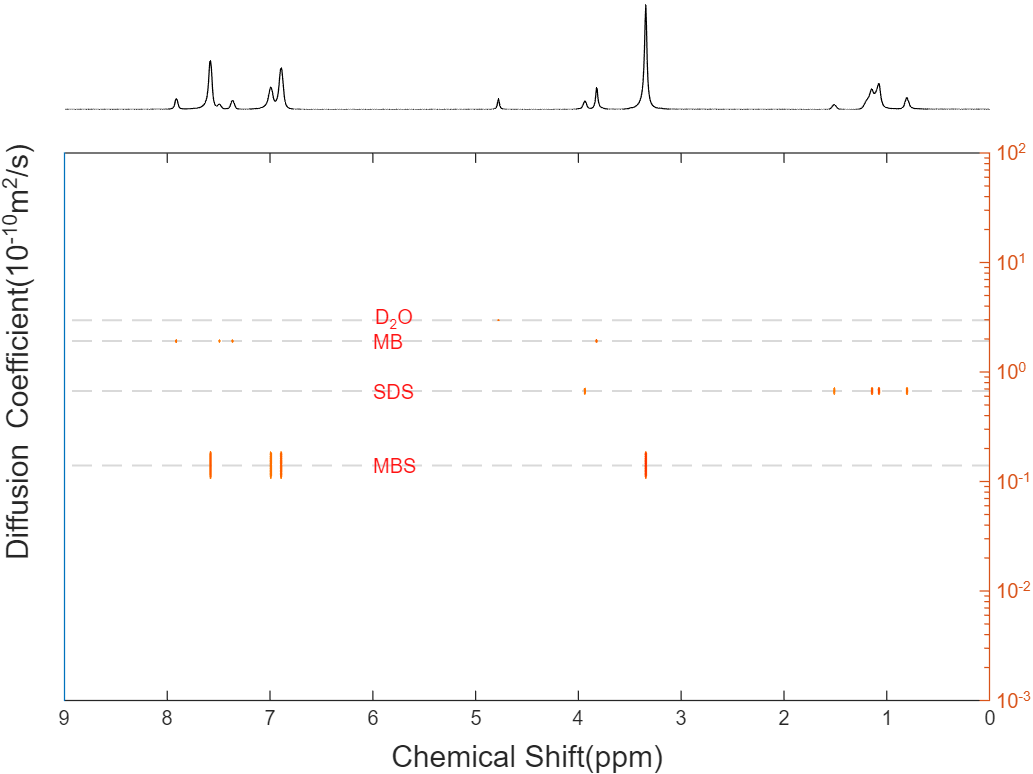

clear, clc;

load MS_high_b.mat
load MS_high_idx_peaks.mat
load MS_high_ppm.mat
load MS_high_HNMR.mat

load MS_high_Result.mat

figure()

t = tiledlayout(5, 1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

cs1 = 0;
cs2 = 9;
dc1 = 1e-3;              
dc2 = 100;

nexttile()
plot(ppm,HNMR, "Color",'k');set(gca,'Xdir','reverse');axis off;
xlim([cs1,cs2]);

nexttile(2, [4, 1])
spec_whole = zeros([length(Z(1, :)), length(ppm)]);
spec_whole(:, idx_peaks) = Z.';
decay_range = linspace(0, 3, length(Z(1, :)));
yyaxis right
[c, h] = contour(ppm,decay_range,spec_whole,40);
set(h.Parent, 'YScale', 'log')

colormap(flipud(autumn));
caxis([-1 1])
set(gca, 'Xdir','reverse'); 

DiffCoef = [0.14, 0.67, 1.92, 2.97];

for i = 1:length(DiffCoef)
    l = line(gca,get(gca,'xlim'),DiffCoef(i)*ones(1,2),'LineWidth',0.8,'color',[0.85 0.85 0.85],'LineStyle','--');
    uistack(l, "bottom");
end

text(6, 0.14, "MBS", FontSize=8, Color=[1, 0.07, 0.07])
text(6, 0.67, "SDS", FontSize=8, Color=[1, 0.07, 0.07])
text(6, 1.92, "MB", FontSize=8, Color=[1, 0.07, 0.07])
text(6, 2.97, "D_2O", FontSize=8, Color=[1, 0.07, 0.07])

xlim([cs1,cs2]);
ylim([dc1,dc2]);
xlabel(t, 'Chemical Shift(ppm)');
ylabel(t, 'Diffusion Coefficient(10^{-10}m^2/s)');
yyaxis left
set(gca, 'YTick', [])

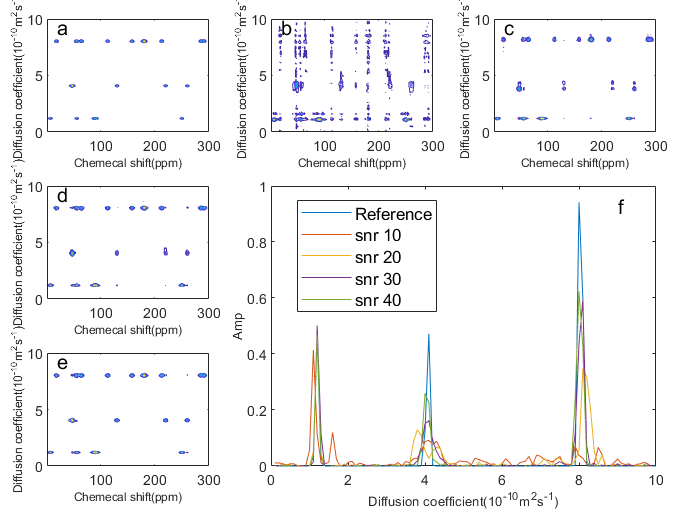

clear
load noise_immunity_result.mat
figure()
t = tiledlayout(3,3);
number = ['a', 'b', 'c', 'd', 'e', 'f'];
for i=1:5

    if i == 5
        nexttile(7)
    else
        nexttile;
    end

    if i==1
        contour(linspace(1, 300, 300), linspace(0.1, 14, 140), squeeze(Z(5, :, :))', 10)
    else
        contour(linspace(1, 300, 300), linspace(0.1, 14, 140), squeeze(Z((i-1), :, :))', 10)
    end
    
    ylim([0, 10])
    text(20, 9.3, number(i), FontSize=12)
    ylabel('Diffusion coefficient(10^{-10}m^2s^{-1})', FontSize=7)
    xlabel('Chemecal shift(ppm)', FontSize=7)
end
nexttile(5, [2, 2])

plot(linspace(0.1, 14, 140), squeeze(sum(Z(5, :, :)))/60, 'DisplayName', 'Reference')
hold on
for i=[1, 2, 3, 4]
    snr = [10, 20, 30, 40];
    plot(linspace(0.1, 14, 140), squeeze(sum(Z(i, :, :)))/60, 'DisplayName', ['snr ', num2str(snr(i))]);
    hold on
end
text(9, 0.93, number(6), FontSize=12)
ylim([0, 1])
xlim([0, 10])
xlabel('Diffusion coefficient(10^{-10}m^2s^{-1})', FontSize=8)
ylabel('Amp', FontSize=8)
legend('FontSize',10, 'Location','best')
t.TileSpacing = 'compact';
t.Padding = 'compact';
exportgraphics(t, 'Results_Graph/Anti_noise_test.png', 'Resolution', 300)

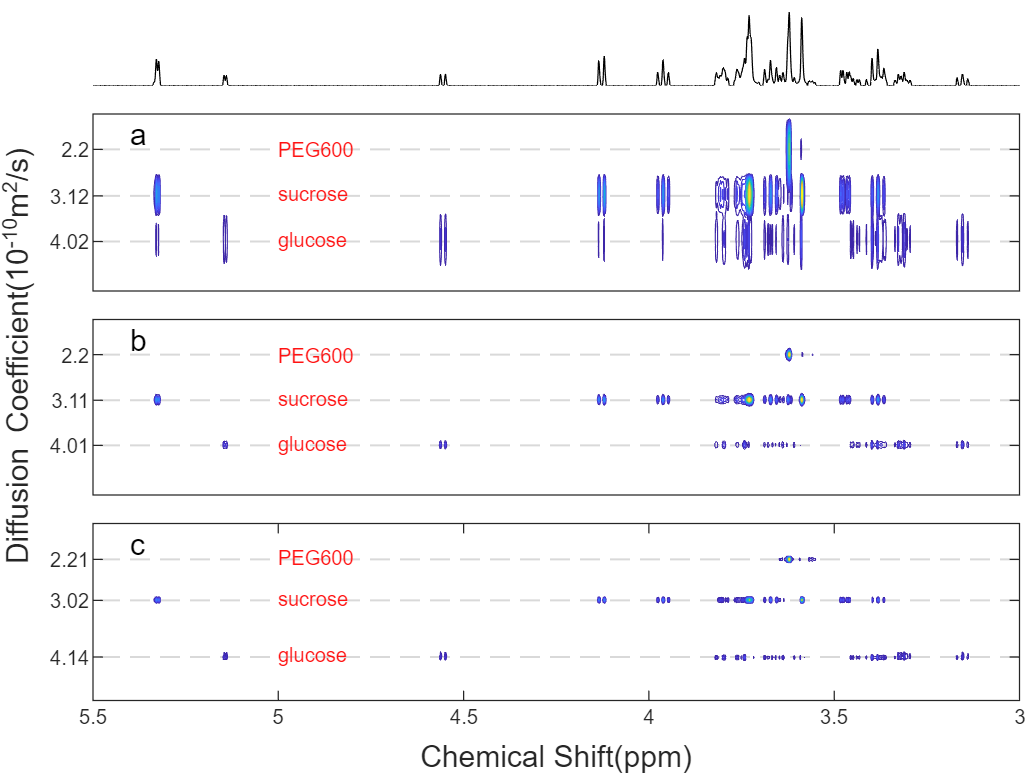

close all;clear;clc

load GSP_b.mat
load GSP_idx_peaks.mat
load GSP_ppm.mat
load GSP_HNMR.mat

load GSP_Result.mat
load GSP_Result_LRsPILT.mat
load GSP_Result_CoMeF.mat

figure()
t = tiledlayout(7,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile

Type = "GSP";

cs1 = 3;
cs2 = 5.5;
dc1 = 1.5;              
dc2 = 5;

cs = [];

contourDOSY(Type, GSP_Result_LRsPILT, GSP_Result_CoMeF, Z, HNMR, b, ppm, cs, idx_peaks, cs1, cs2, ...
            dc1, dc2, t);